# More Practice with Images

This reading will walk you through some more image processing techniques by recreating the images shown in the *Feature Engineering and Clustering Video*.

## Load and Examine the Image

The image used is part of an example included with the Computer Vision Toolbox in MATLAB. You read images into MATLAB using the `imread` function, using the file name as input. Here, we need the full path to the file, but if the image is in your Current Folder or on your search path, you can just use the filename. 

Run this section to load the image and view the size.

fname = '/Applications/MATLAB_R2020a.app/toolbox/vision/visiondata/stopSignImages/image021.jpg';
% Read in the file
stop = imread(fname);
% View the size of the image
numDimension = size(stop)

numDimension =         1000        1504           3


The image is a color image. The first two dimensions are the rows and columns, or number of pixels in y and x directions. The 3rd dimension has 3 planes, or sheets. These specify the intensity of red, green, and blue combination that make up the pixel color. A color image will always have a size of `[Ypixels, Xpixels, 3]. `This is in contrast to a grayscale image which is just a matrix. The value of at each matrix location specifies the brightness of that pixel.

View the image with the `imshow` function.

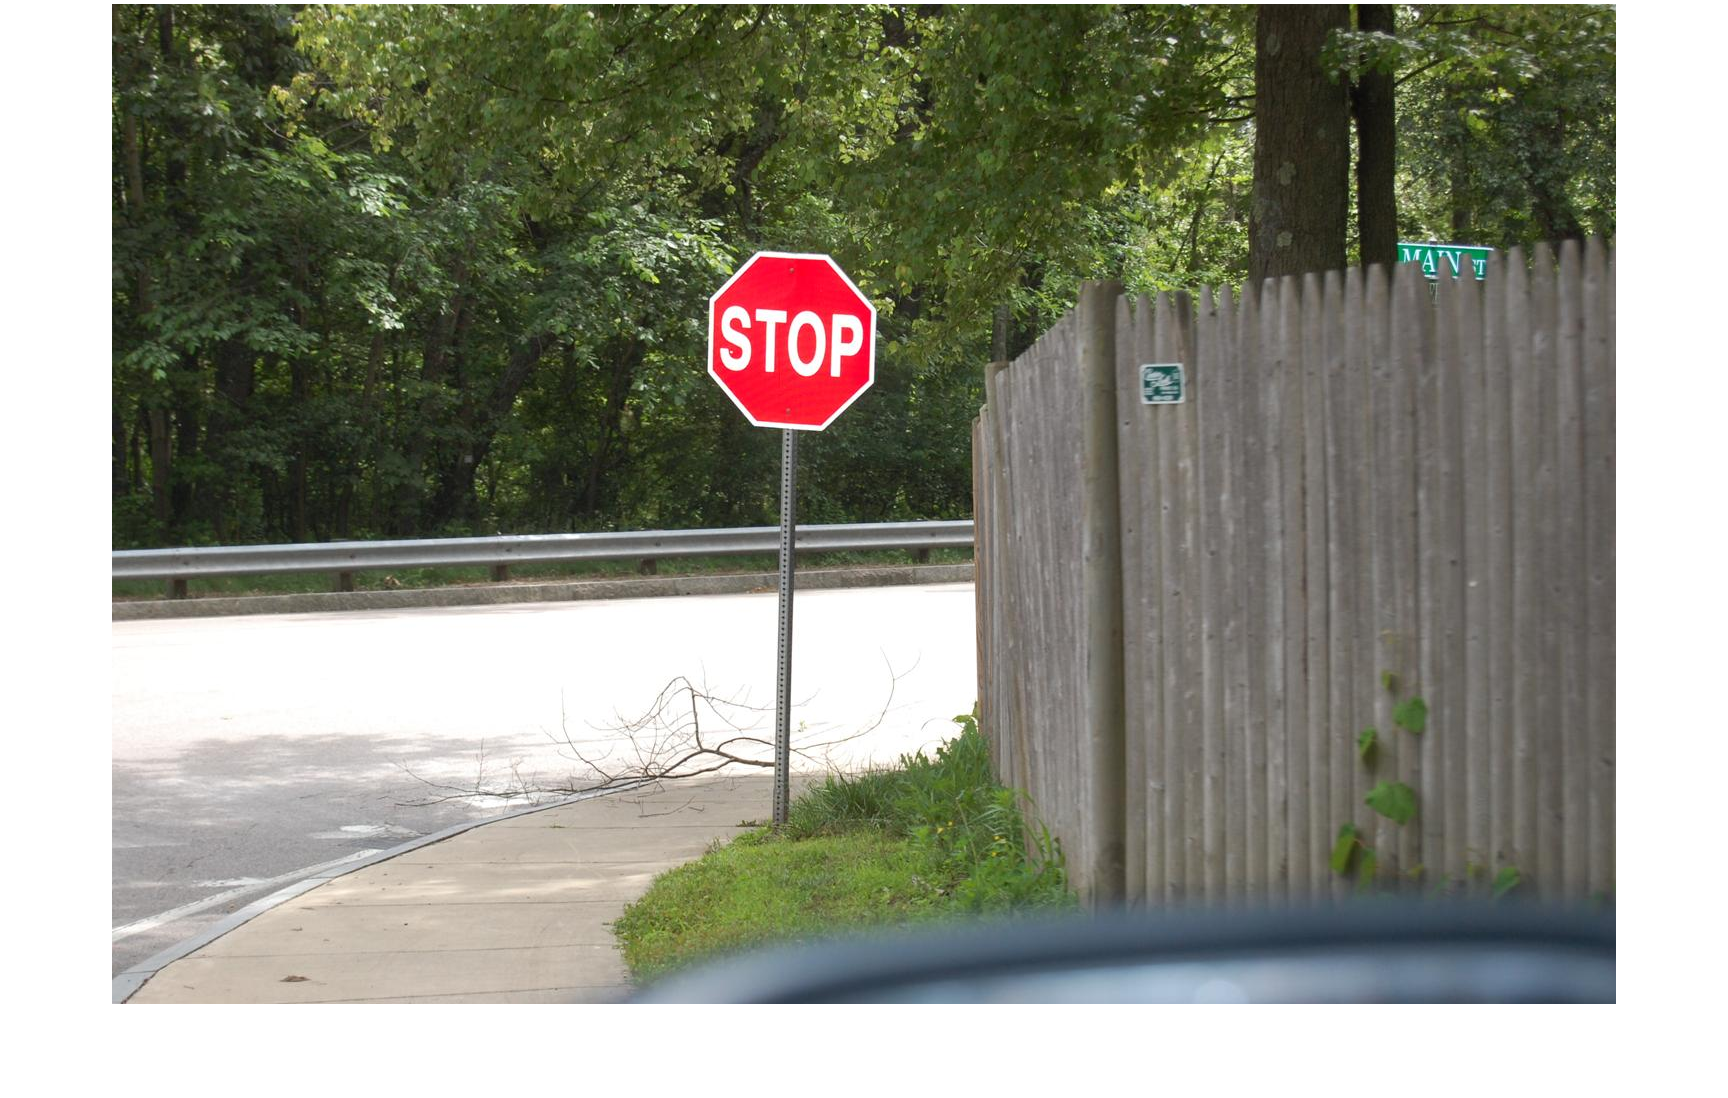

imshow(stop)

## Isolate the Edges of the Letters

There are many approaches to isolating only the edges of the letters. Many are very complicated. However, you can accomplish the task using the Image Segmenter App and a few functions.

#### Step 1: Perform edge detection

There is a function named `edge` that returns a binary image with `true` for each pixel found to be an edge pixel and false if the pixel is not an edge pixel.

Many image processing functions require a grayscale image as input. So, the code below first converts the image to grayscale using the `rgb2gray` function, then performs edge detection.

stopGray = rgb2gray(stop);
stopEdge = edge(stopGray);
imshow(stopEdge)

#### Step 2: Isolate the letters using the Image Segmenter App

The function below named `stopSignLetters `was created using the Image Segmenter App. A "Flood Fill" operation was used to segment the letters. Flood Fill enables you to click on a location in the image, and then similar pixels in the region are identified. The downside is because the operation depends on where you click in the App, it is *not* easy to reproduce the results across many images. But if you're just working with a few images, it is a fast way to segment them.  

Try opening the Image Segmenter App and load the **stop** image from the workspace to see if you can create a mask just containing the letters in the stop sign.** Replace the function below with one you create in from the app.**

bwLetters = stopSignLetters(stop);
imshow(bwLetters)

#### Step 3: Combine the mask returned from the edge function with the mask created from the app

It is often necessary to combine multiple masks. Below, the mask **letters** is true only when a pixel value was identified as true from the edge operation and from the mask returned by the Image Segmenter App. 

letters = bwLetters & stopEdge;
imshow(letters)

## Isolating the Entire Stop Sign

The Image Segmenter App also lets you draw custom shapes. Under "Add to Mask" select "Draw ROIs" or region of interest. The function `stopSignShape` was created this way. Like Flood Fill, this is not always easy to apply to many images. However, if you have just a few images or a series of images with an object in the same location that you need to isolate or remove, this is useful.

stopShape = stopSignShape(stop);
imshow(stopShape)

## Isolating Color

So far you've seen segmentations done using the Image Segmenter App. The function `stopSignColor` used below as created using the Color Thresholder App. Like the Image Segmenter App you can convert the image to different color spaces and try multiple approaches. Open the app and load the **stop** image from the Workspace. Can you create a segmentation similar to below?

redmask = stopSignColor(stop);
imshow(redmask)

#### Applying a Mask to a Color Image

Now you have a mask for specifying the location of red in the stop sign. For my `stopSignColor` segmentation, this was enough. However, if you still had red from the environment, you could combine this with the mask of the stop sign shape, similar to how the edges of the letters were created.

To create a color image of just the red sign, the mask needs to be applied to all three color planes. That is, for pixels where the mask is true, preserver the red, green, and blue values of the pixel. For all the false mask locations, set the values to 0. This is done using the `repmat` function, which repeats the mask 3 times in the 3rd dimension. The result is a mask that is the exact same size as the color image.

% Copy the original image into a new variable
stopColorimg = stop;
% Repeat the mask. Use the negation operator, ~, to specify that everywhere
% NOT in the mask should be changed to 0.
stopColorimg(repmat(~redmask, [1 1 3])) = 0;
imshow(stopColorimg)

## Adjust the Intensity

Recall from video that Image Segmenter app prompted us with a question about adjusting the image contrast. That is done with the imadjust function. You can also use this to make color images appear brighter or darker. The 2nd input is a 2x3 matrix. The first row specifies the low contrast limits and the second row the high contrast limits. Try adjusting the values and visualizing the results.

darkImage = imadjust(stop, [0.7 0.4 0.4; 1 1 1]);
imshowpair(stop, darkImage, "montage")

## Saving Images

Now you've seen how the opening images in the video were created! You can save images using the `imwrite `function. There are many different file types and different options for the different file types. The "Quality" option specifies the jpeg compression. Higher values will result in larger file sizes, but more accurately represent the original image. Uncomment the lines if you want save the images.

% imwrite(stop, "stop sign.jpg", "Quality", 100)
% imwrite(letters, "stop letters.jpg", "Quality", 100)
% imwrite(stopShape, "stop shape.jpg", "Quality", 100)
% imwrite(stopColorimg, "stop color.jpg", "Quality", 100)
% imwrite(darkImage, "stop dark.jpg", "Quality", 100)